# Dynamic Bending Test Rig

## **12.500 Hz is the required actuator bandwidth, and the requried force is 16.8787 lbf as per section 2.2 . Assuming that you are interested in replicating the force (rather than displacement)**

**Potentially look at decreasing required actuator bandwidth by smoothing out the function? So ignoring the decrease that occurs between 5.5 and 5.7**

## 1 Actuator Sizing from Shear Forces MATLAB (as of 3/6/26)

Now, I have a force/time graph from the previous detailed shear force analysis. 

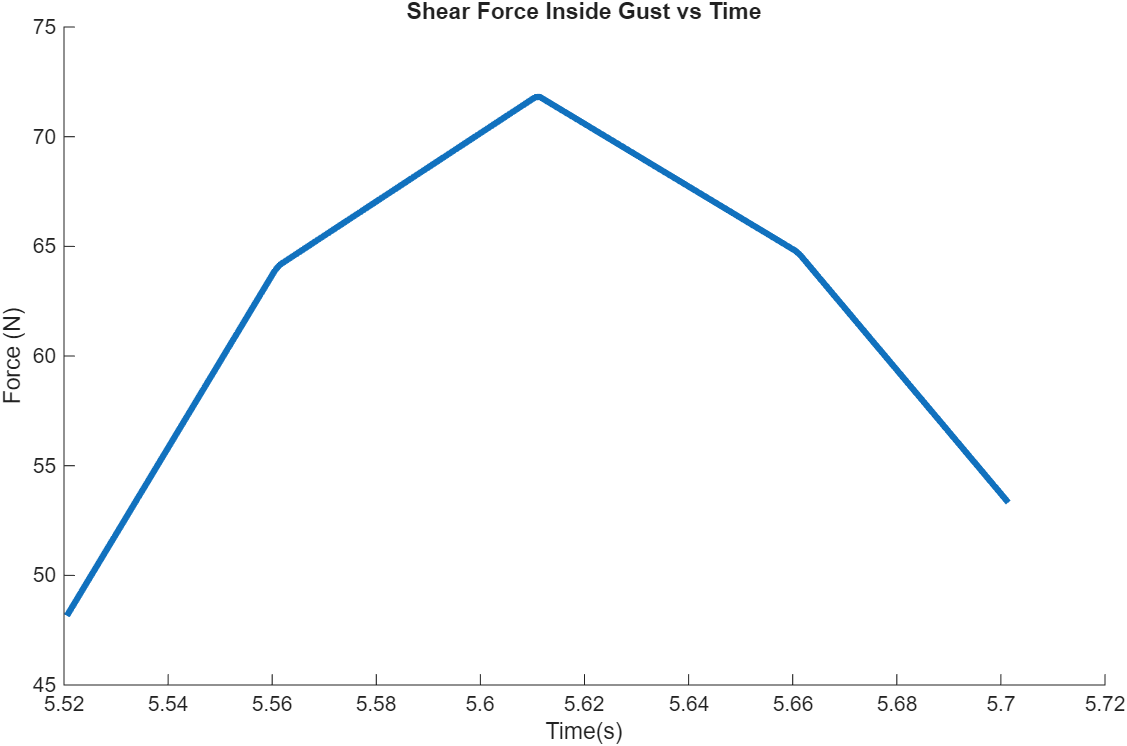

But we are unsure about the validity of this. A way to confirm the validity would be to compare it to a 'vector projection' of the max shear to the angle of attack, using small angle approximation

Quickest ramp looks to be 

timeForceRamp = 5.56-5.52

timeForceRamp = 0.0400

freqTimeRamp = 1/timeForceRamp 

freqTimeRamp = 25.0000

deltaForce = 63 - 55

deltaForce = 8

## 2.1 Actuator Sizing from Gust Velocity Profile & Ian's Calculations

From Ian's Shear Calculations (at 1.7 AoA):

[https://docs.google.com/spreadsheets/d/1YpCOBGyIhGbyl9DqY5GLDXi1CcHhjao9K5FwuqBK1_Q/edit?usp=sharing](https://docs.google.com/spreadsheets/d/1YpCOBGyIhGbyl9DqY5GLDXi1CcHhjao9K5FwuqBK1_Q/edit?usp=sharing)

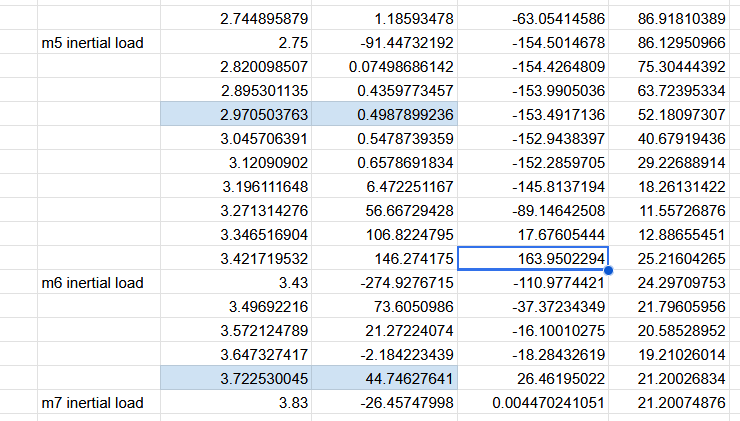

`164 N `is the max shear, which is about `36.8687 lbf`

From MATLAB code for the Cosine Gust:

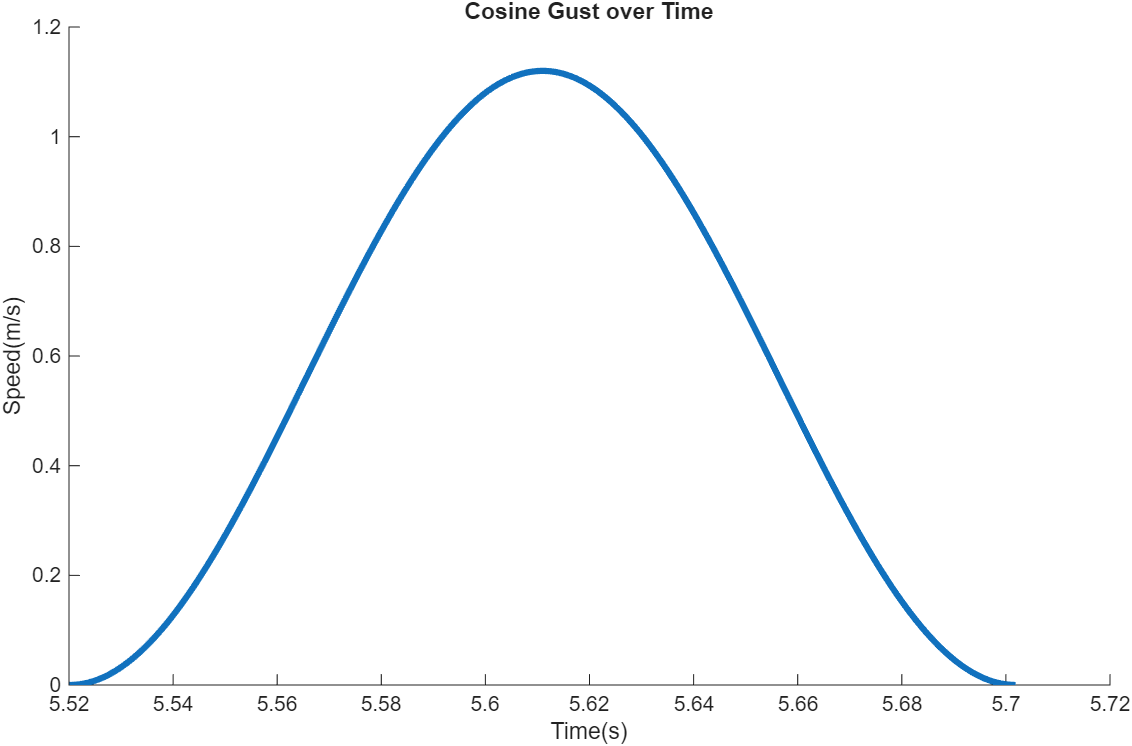

The time this occurs at is around 5.52s to 5.7s, which results in  a 0.18s time for the gust

Apply a factor of safety of two, so that there is a 0.09s cycling requirement for the cosine gust.

This results in the required bandwidth being as follows(from here) [https://en.wikipedia.org/wiki/Amplifier_figures_of_merit?](https://en.wikipedia.org/wiki/Amplifier_figures_of_merit?utm_source=chatgpt.com):


$$f = \frac{3}{.09$$


fBW1 = 3/.09 % in Hz

fBW1 = 33.3333

## 2.2 Gust Shear Profile Based Off OpenRocket AoA & Ian's Calculations

Take the AoA profile from OpenRocket and multiply it by Ian's peak shear at peak angle of attack to transform the AoA curve to a shear curve

%% OpenRocket CSV -> Angle of Attack vs Time & Altitude (robust)
% - Handles OpenRocket comment lines (# ...)
% - Uses the detected header line for variable names
% - Robustly finds Time / Altitude / AoA columns
% - Forces vectors to be column vectors to avoid table row-size errors

clear; clc;

filePath = "OpenRocket.csv";   % or full path if needed

%% 1) Find the header line + first data line (first non-# line)
fid = fopen(filePath,'r');
assert(fid ~= -1, "Could not open file: %s", filePath);

headerLine = "";
dataStartLine = NaN;

lineNum = 0;
while ~feof(fid)
    lineNum = lineNum + 1;
    ln = fgetl(fid);
    if ~ischar(ln), break; end
    lnTrim = strtrim(ln);

    % OpenRocket commonly writes: "# Time (s),Altitude (m),..."
    if startsWith(lnTrim, "#") && contains(lnTrim, "Time") && contains(lnTrim, "Altitude")
        headerLine = erase(lnTrim, "#");
        headerLine = strtrim(headerLine);
    end

    % First actual data row is typically the first non-# line
    if ~startsWith(lnTrim, "#") && ~isempty(lnTrim) && isnan(dataStartLine)
        dataStartLine = lineNum;
        break;
    end
end
fclose(fid);

assert(~isempty(headerLine), "Couldn't find the OpenRocket header row (the '# Time...,Altitude...' line).");
assert(~isnan(dataStartLine), "Couldn't find the first data row (first non-# line).");

%% 2) Build MATLAB-friendly variable names from the header
rawNames = split(headerLine, ",");
rawNames = strtrim(rawNames);

% makeValidName removes spaces/symbols so e.g. "Time (s)" -> "Times"
varNames = matlab.lang.makeValidName(rawNames, "ReplacementStyle","delete");

%% 3) Read numeric data from the first data line onward
opts = delimitedTextImportOptions("NumVariables", numel(varNames));
opts.DataLines = [dataStartLine, Inf];
opts.Delimiter = ",";
opts.VariableNames = varNames;
opts.VariableTypes = repmat("double", 1, numel(varNames));
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

T = readtable(filePath, opts);

%% 4) Find the Time / Altitude / AoA columns (works with unit-suffixed names)
names = string(T.Properties.VariableNames);

% exact-match candidates (common OpenRocket outputs after makeValidName)
timeCandidates = ["Times","Time_s","Time","time","TimeSeconds"];
altCandidates  = ["Altitudem","Altitude_m","Altitude","altitude"];
aoaCandidates  = ["AngleOfAttack","AngleOfAttack_deg","Angle_of_attack","AoA","alpha"];

timeVar = intersect(timeCandidates, names, "stable");
altVar  = intersect(altCandidates,  names, "stable");
aoaVar  = intersect(aoaCandidates,  names, "stable");

% fallback: contains (case-insensitive)
if isempty(timeVar)
    timeVar = names(contains(lower(names), "time"));
end
if isempty(altVar)
    altVar = names(contains(lower(names), "altitude"));
end
if isempty(aoaVar)
    aoaVar = names(contains(lower(names), "angleofattack") | contains(lower(names), "aoa"));
end

assert(~isempty(timeVar), "Couldn't find Time column. Columns found: %s", strjoin(names, ", "));
assert(~isempty(altVar),  "Couldn't find Altitude column. Columns found: %s", strjoin(names, ", "));
assert(~isempty(aoaVar),  "Couldn't find Angle of attack column. Columns found: %s", strjoin(names, ", "));

% pull data
t   = T.(timeVar(1));
alt = T.(altVar(1));
aoa = T.(aoaVar(1));

%% 5) Force all to be column vectors (fixes 'same number of rows' table error)
t   = t(:);
alt = alt(:);
aoa = aoa(:);

% assert(numel(t)==numel(alt) && numel(t)==numel(aoa), ...
%     "Lengths mismatch: t=%d, alt=%d, aoa=%d", numel(t), numel(alt), numel(aoa));
% 
% AoA_Time_Altitude = table(t, alt, aoa, ...
%     "VariableNames", ["Time_s","Altitude_m","AngleOfAttack_deg"]);
% 
% % 6) Display + plots
% disp("Detected columns:");
% disp("  Time:     " + timeVar(1));
% disp("  Altitude: " + altVar(1));
% disp("  AoA:      " + aoaVar(1));
% 
% disp(AoA_Time_Altitude(1:min(10,height(AoA_Time_Altitude)), :));
% 
% figure;
% plot(AoA_Time_Altitude.Time_s, AoA_Time_Altitude.AngleOfAttack_deg);
% xlabel("Time (s)"); ylabel("Angle of attack (deg)");
% grid on; title("Angle of Attack vs Time");
% 
% figure;
% scatter(AoA_Time_Altitude.Altitude_m, AoA_Time_Altitude.AngleOfAttack_deg, 10, "filled");
% xlabel("Altitude (m)"); ylabel("Angle of attack (deg)");
% grid on; title("Angle of Attack vs Altitude");

Then to generate the graph for shear (from the max shear calculated via CFD at 1.7 AoA):

`164 N` ~ `36.8687 lbf`

shearMax = 36.8687

shearMax = 36.8687

shearGraph = aoa*shearMax

shearGraph = 1.0e+03 *

    3.3186
    3.3165
    3.2489
    3.0736
    2.8306
    2.4694
       NaN
    2.0681
    1.7153
    1.4449
    1.2379
    1.0752
    0.9464
    0.8408
    0.7541


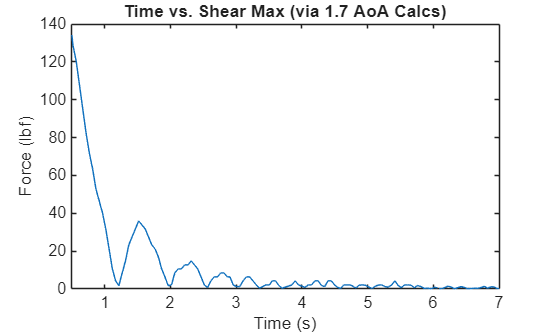


figure
plot(t,shearGraph)
xlim([0.5, 7])
title("Time vs. Shear Max (via 1.7 AoA Calcs)")
xlabel("Time (s)"); ylabel("Force (lbf)")

Look athte 6.6 AoA

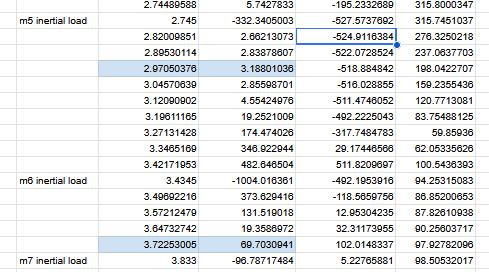

524.9116 N ~  118.00482242 lbf

shearMax = 118.00482242

shearMax = 118.0048

shearGraph = aoa*shearMax

shearGraph = 1.0e+04 *

    1.0622
    1.0615
    1.0399
    0.9837
    0.9060
    0.7904
       NaN
    0.6619
    0.5490
    0.4625
    0.3962
    0.3441
    0.3029
    0.2691
    0.2414


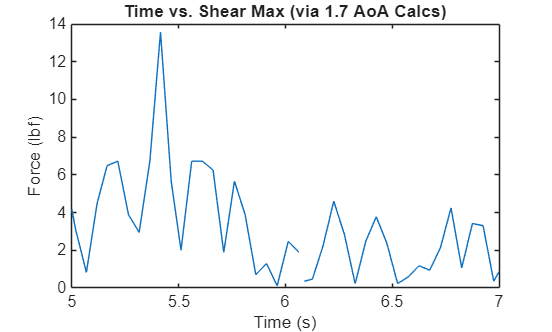


figure
plot(t,shearGraph)
xlim([5, 7])
title("Time vs. Shear Max (via 1.7 AoA Calcs)")
xlabel("Time (s)"); ylabel("Force (lbf)")

This amount of force looks to be too conservative. Did FEA for Stroke Length

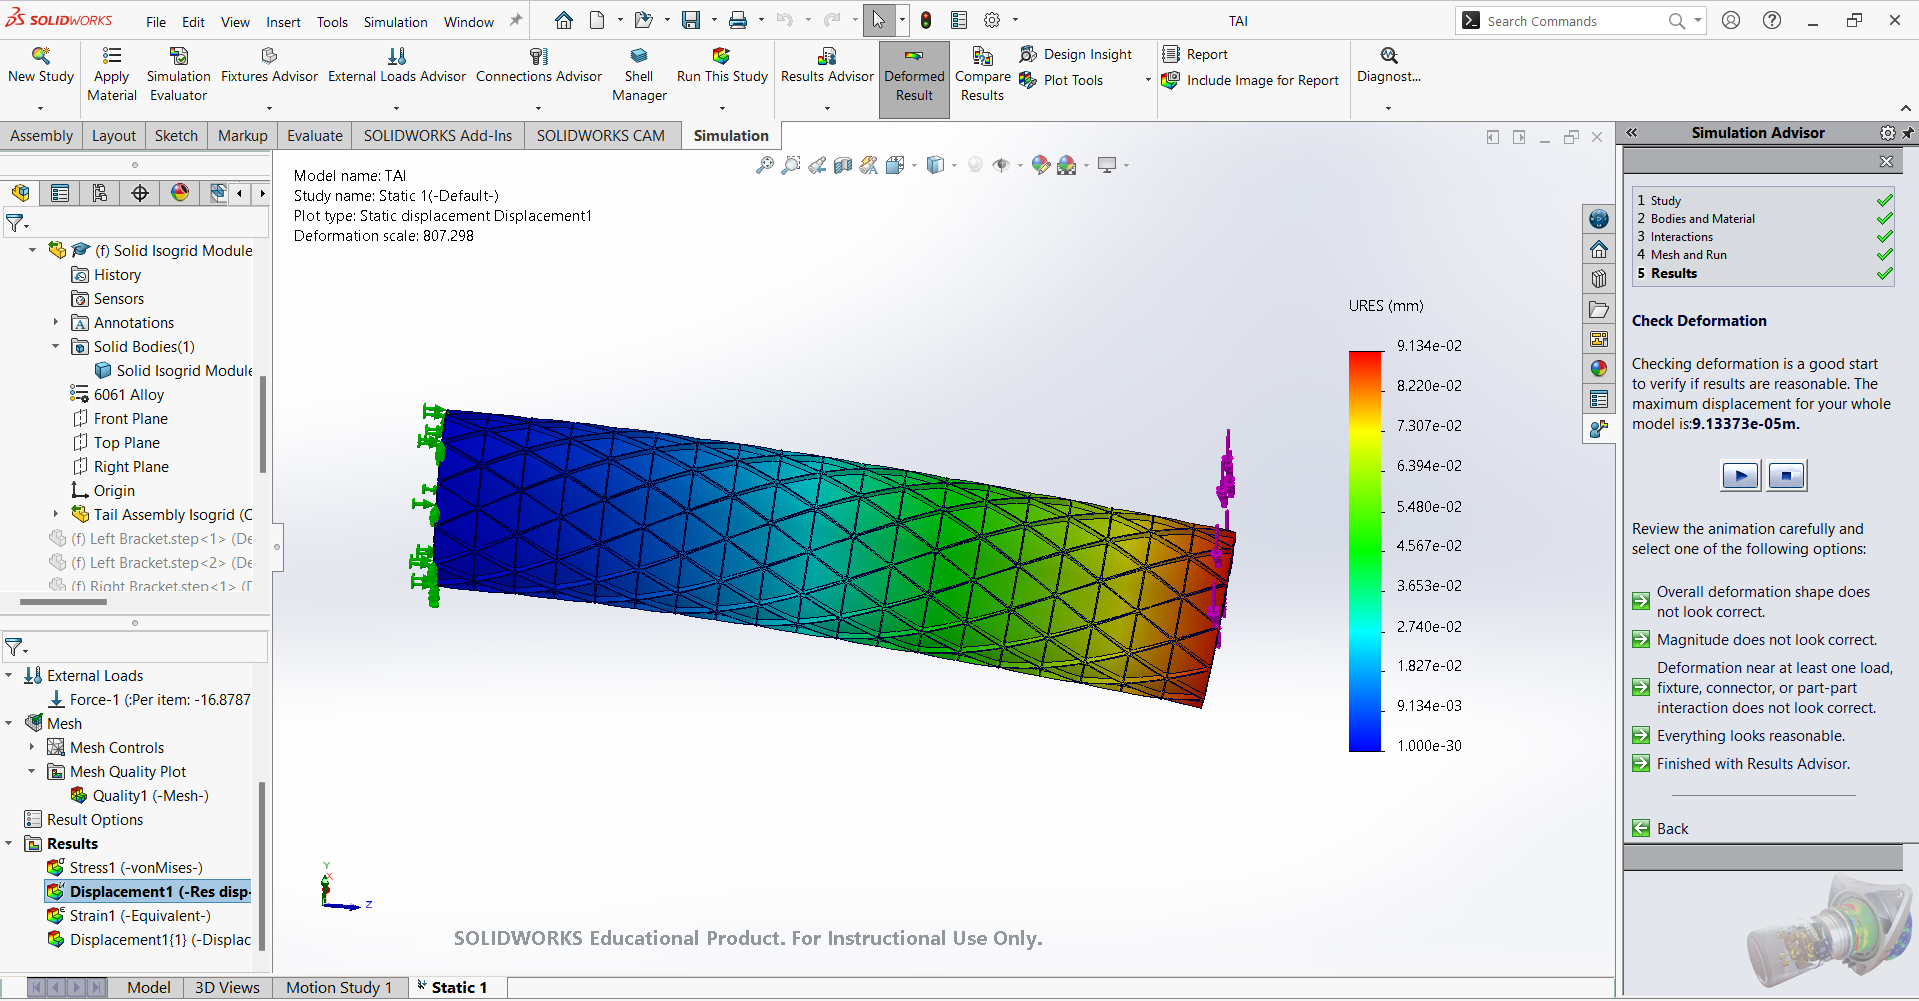

Thereforce, stroke length = 9.13373*10^-5 m for the solid isogrid.

For the open web...

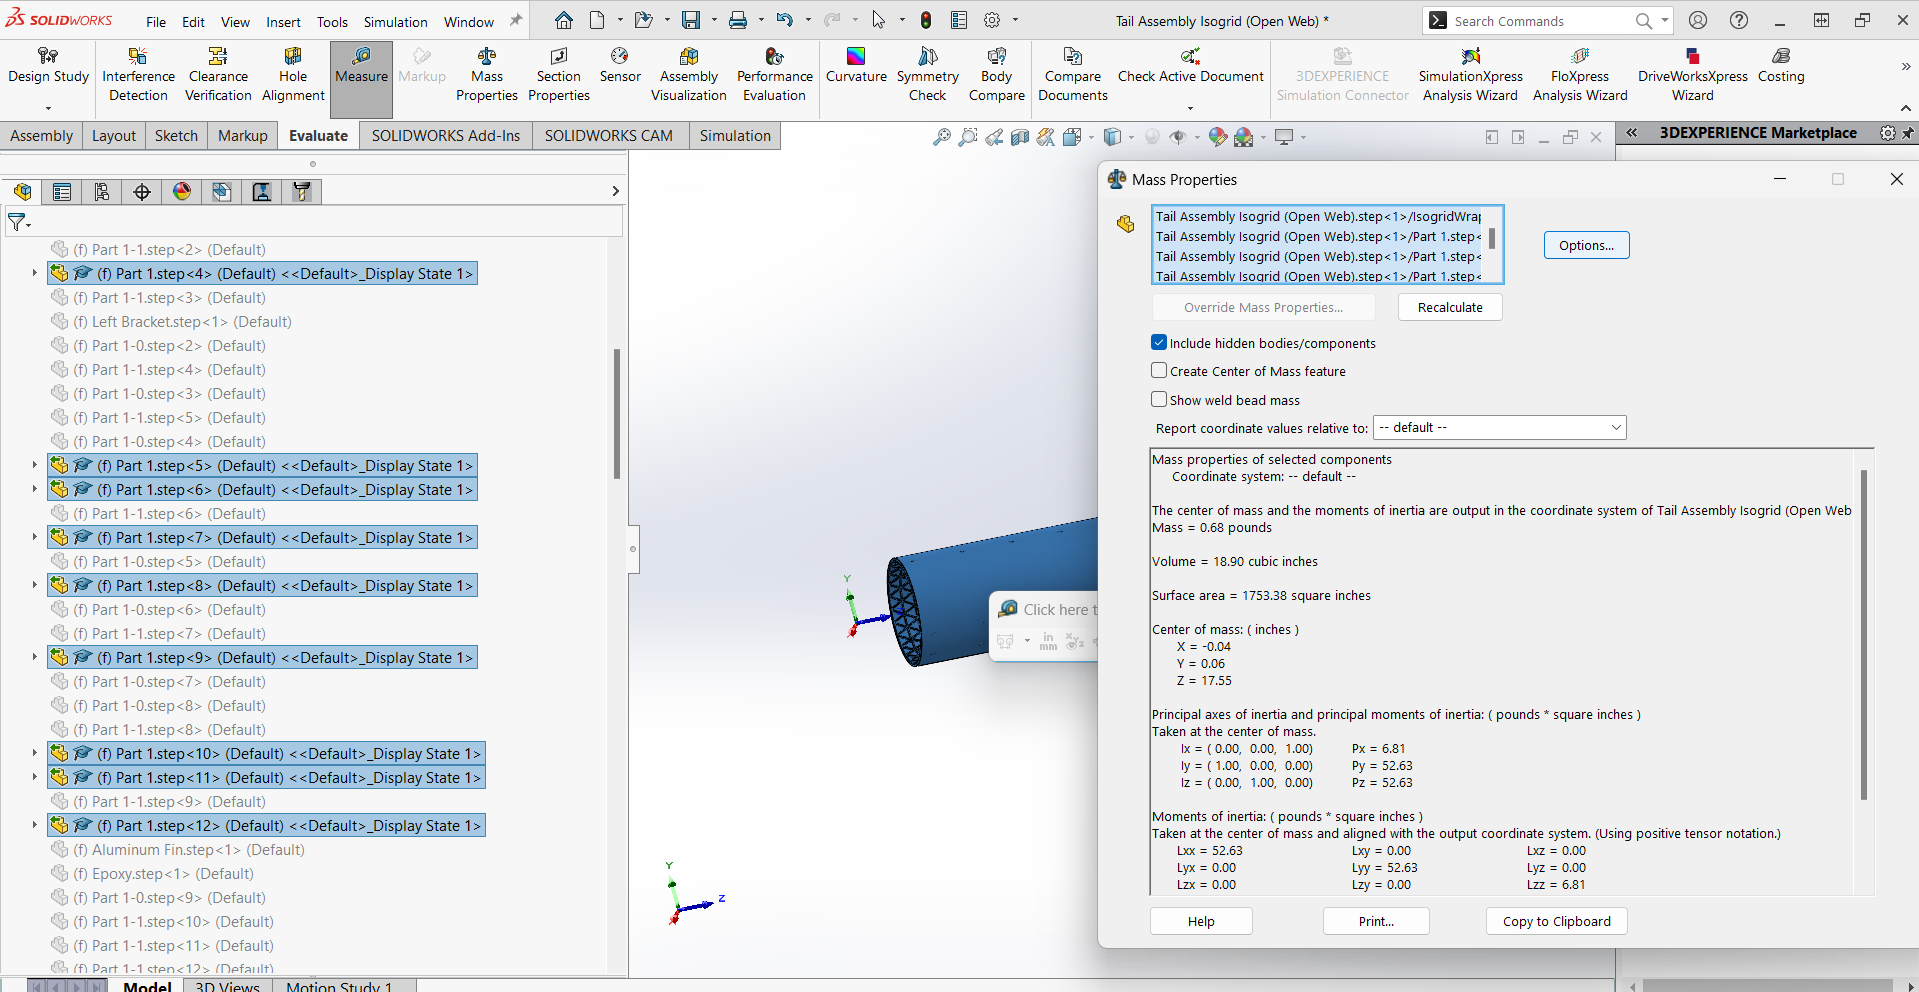

Volume = 18.90 inches

Let's look at 1.7 AoA and get the limits to get a better look at the quickest ramp required:

shearMax = 36.8687

shearMax = 36.8687

shearGraph = aoa*shearMax

shearGraph = 1.0e+03 *

    3.3186
    3.3165
    3.2489
    3.0736
    2.8306
    2.4694
       NaN
    2.0681
    1.7153
    1.4449
    1.2379
    1.0752
    0.9464
    0.8408
    0.7541


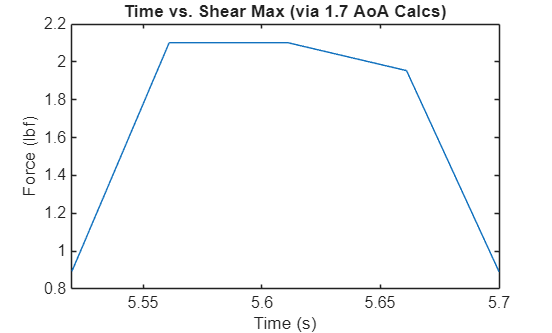


figure
plot(t,shearGraph)
xlim([5.52 5.7])
title("Time vs. Shear Max (via 1.7 AoA Calcs)")
xlabel("Time (s)"); ylabel("Force (lbf)")

## 2.3 Sizing Actuator Bandwidth and Required Force, Based Off OpenRocket AoA & Ian's Calculations

Time is at 5.64 to 5.72~

0.08s required for the cycle, and then bandwidth would be

FBW2 = 1/.08

FBW2 = 12.5000

## **12.500 Hz is the required actuator bandwidth, and the requried force is 16.8787 lbf**

These calculations are more conservative than the previous guesstimate, so use this instead. The 2x required force from the 1.7 AoA is used in the above conclusion

But what if I removed that drop  that occurs at 5.65 seconds? then I would be looking at 5.700 - 5.525

FBW2smoothed = 1/(5.700 - 5.525)

FBW2smoothed = 5.7143

## 2.3 Calculate Displacement Over Time Due to Shear

Please see the PDF below for an inititial displacement estimation:

**Thin Walled Cylinder Approximation for Deflection**

**From Onshape CAD**

R = 3.02"

r = 3"

length = 29.996"

Rtwc = 3.020

Rtwc = 3.0200

rtwc = 3

rtwc = 3

htwc = 29.996

htwc = 29.9960


volTWC = pi*(Rtwc^2-rtwc^2)*htwc

volTWC = 11.3459


% from Shigley's, table A-5 for aluminum alloy
rho6061 = 0.098 % lbf/in^3

rho6061 = 0.0980


% from Shigley's, table A-5 for aluminum alloy
E6061 = 10.4*10^6 % psi

E6061 = 10400000


% calc mass
massTWC = rho6061*volTWC

massTWC = 1.1119


% need to load the shear somehow from the .mat, as well as the time
% from the prev. detailed analysis we did
shearDGustProfile = load('shearDGustProfile.mat');

% import time data for shear
shearDGustTimeDis = load('shearDGustTimeDist.mat')

shearDGustTimeDis = struct with fields:
    gustArray: [200×4 double]




Ptwc = shearDGustProfile.totalShearFnOfGustVel(:,1)

Ptwc =    48.1568
   48.5147
   48.8727
   49.2306
   49.5886
   49.9465
   50.3045
   50.6624
   51.0204
   51.3783
   51.7363
   52.0942
   52.4522
   52.8101
   53.1681


shearTimeArr = shearDGustTimeDis.gustArray(:,1)

shearTimeArr =     5.5206
    5.5215
    5.5224
    5.5233
    5.5242
    5.5251
    5.5260
    5.5269
    5.5278
    5.5287
    5.5296
    5.5306
    5.5315
    5.5324
    5.5333


% conversion factor is for newtons to lbs (1/4.448)

Ptwc = Ptwc/4.448

Ptwc =    10.8266
   10.9071
   10.9876
   11.0680
   11.1485
   11.2290
   11.3095
   11.3899
   11.4704
   11.5509
   11.6314
   11.7118
   11.7923
   11.8728
   11.9533



% area moment of inertia for tube
Dtwc = Rtwc*2

Dtwc = 6.0400

dtwc = rtwc*2

dtwc = 6


aITWC = ((Dtwc^4 - dtwc^4)*pi)/64

aITWC = 1.7135


% now that we have all the information for thin wall deflection...
% calculate it!:

defBendTWC = (Ptwc.*(htwc^3))/(3*E6061*aITWC)

defBendTWC =     0.0055
    0.0055
    0.0055
    0.0056
    0.0056
    0.0057
    0.0057
    0.0058
    0.0058
    0.0058
    0.0059
    0.0059
    0.0060
    0.0060
    0.0060



$$Recall: V \propto A \propto I$$


Use this relationship to estimate a ratio between the $I_{isogrid$ and $I_{TWC}$

From previous calculations (units are in^3).

Where V_twc is manually calculated, and V_iso is recorded from onshape


$$\frac{V_{iso}}{V_{TWC}}= \frac{25.029}{11.3491}= 2.2059$$



$$Recall: \delta_{b} = \frac{PL^3}{3EI} \\
$$


Then, using the ratio and proportionalities established above:


$$\delta_{b,isogrid} = \frac {1}{2.2059}\delta_{b,TWC} \\
\delta_{b,isogrid} = 0.4533*\delta_{b,TWC}$$


Using this ratio, then plug-in numbers for the calculated shear so you can be a force vs. displacement profile to match with actuators.

Note that from FEA there is an error of 6.8982%. This could be because the arc rings are not included in the CAD for the FEA, which could have reduced expected length. Still good nonetheless.

% user inputted from previous analyses:
twcTOISOFACTOR = 2.2059

twcTOISOFACTOR = 2.2059


defBendISOEst =  defBendTWC/twcTOISOFACTOR

defBendISOEst =     0.0025
    0.0025
    0.0025
    0.0025
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0026
    0.0027
    0.0027
    0.0027
    0.0027
    0.0027



% now graph force/displacement
Piso = Ptwc

Piso =    10.8266
   10.9071
   10.9876
   11.0680
   11.1485
   11.2290
   11.3095
   11.3899
   11.4704
   11.5509
   11.6314
   11.7118
   11.7923
   11.8728
   11.9533


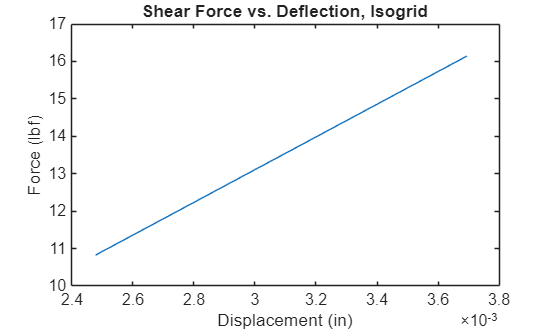


figure;
plot(defBendISOEst, Piso)
title('Shear Force vs. Deflection, Isogrid'); xlabel('Displacement (in)'); ylabel('Force (lbf)')

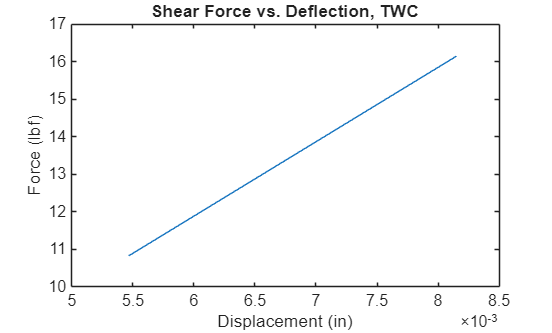



figure;
plot(defBendTWC, Ptwc)
title('Shear Force vs. Deflection, TWC'); xlabel('Displacement (in)'); ylabel('Force (lbf)')

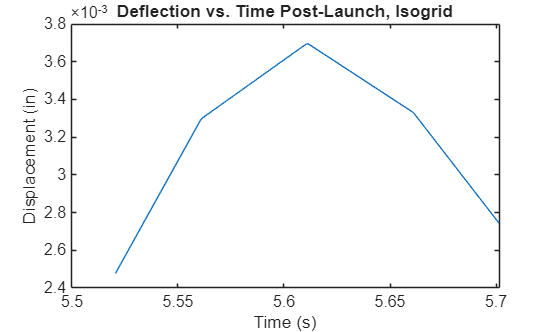


% new graph, displacement over time
plot(shearTimeArr, defBendISOEst)
title('Deflection vs. Time Post-Launch, Isogrid'); xlabel('Time (s)'); ylabel('Displacement (in)')

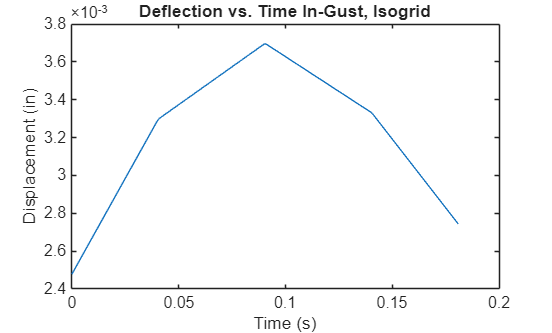


% new graph, time shifted for 0 - whatever seconds
min_valTime = min(shearTimeArr);
shearTimeArr0Shift =  shearTimeArr - min_valTime;

plot(shearTimeArr0Shift, defBendISOEst)
title('Deflection vs. Time In-Gust, Isogrid'); xlabel('Time (s)'); ylabel('Displacement (in)')

## 2.4 Calculate Required Acceleration from Graph

## 3.1 Actuator Choice: Calculating how actuator maps to speed requirements (if we were interested in displacement)

A consideration I had was whether or not we wanted to replicate the displacement caused by the shear forces. To analyze  what kind of actuator we would need if we wanted to replicate dispalcement(as well as force application), I applied calculations that assumed simple harmonic movement of a lienar actuator.

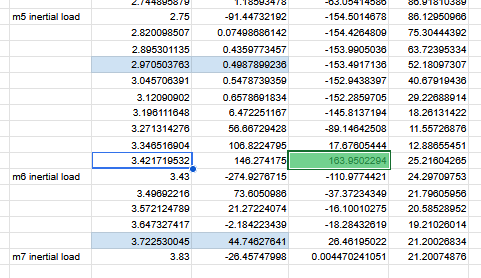

From the figure above(Ian's Calcualtions), grab the lever arm as the length form the nose cone to the point of max shear

leverArm = 3.417 % in m

leverArm = 3.4170

Using the radius, and recalling that for SHM:

X(t) = 


% Used FEA to get the displacement below
strokeLength =  9.13373*10^-5 % in m

strokeLength = 9.1337e-05



% peak velocity
velPeakMS = 2*pi * FBW2*strokeLength % in m/s

velPeakMS = 0.0072

velPeakmillMS = velPeakMS*100

velPeakmillMS = 0.7174


velPeakSmoothed = 2*pi*FBW2smoothed*strokeLength

velPeakSmoothed = 0.0033


$$V_{max} = 2 \pi fA \
$$


% peak acceleration
accPeak = ((2*pi * FBW2)^2)*strokeLength% in m/s

accPeak = 0.5634

These values indicate that looking to replicate the displacement as well as the force profile would prove expensive, due to it requiring a peak velocity at 46.8395 m/s , and a peak acceleration of 

Required Rise TIme:

0.08s for the 

This guesstimation of a stroke length of 0.2982 seems to be too large. Let's sanity check that

## 3.2.1 Options for Actuators that Meet Requirements, HS Electric LA

Firgelli High Speed Linear Actuator

[https://cdn-firgelliauto.sfo2.cdn.digitaloceanspaces.com/product-downloads/linear-actuator/firgelli-high-speed-linear-actuator-spec-sheet.pdf](https://cdn-firgelliauto.sfo2.cdn.digitaloceanspaces.com/product-downloads/linear-actuator/firgelli-high-speed-linear-actuator-spec-sheet.pdf)

**Look at the force requirement**

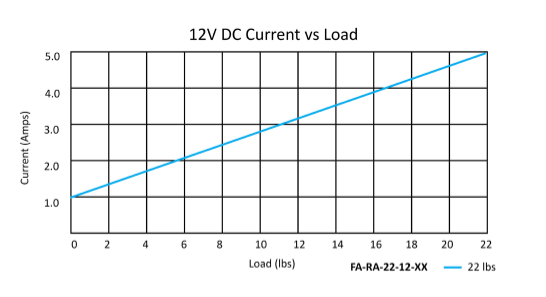

**Look at velocity(bandwidth) requirement**

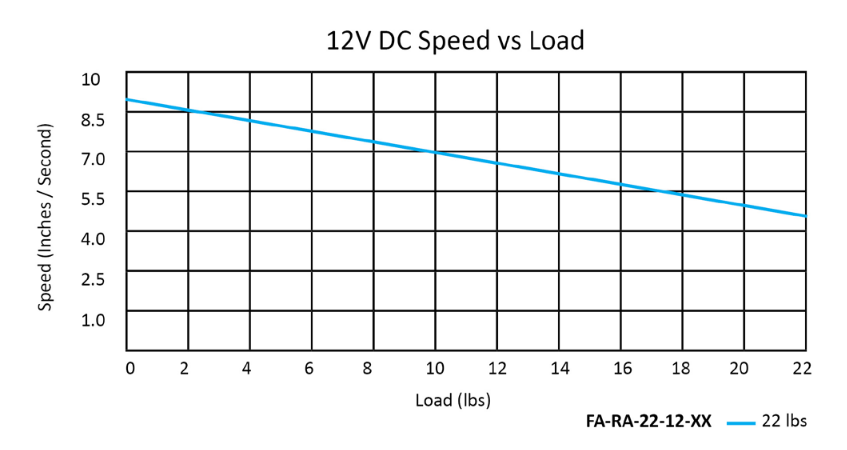

Does not meet speed requirement. (7 in/s at 8 lbf) v_la = 0.185 m/s . This is way under velocity peak of 46.8395

% look at the speed requirement
v_la = 0.185

v_la = 0.1850

freqEstLA = v_la/(2*pi*strokeLength) % in Hz

freqEstLA = 322.3619

Waay too slow

## 3.2.2 Options for Acutators that Meet Requirements, Voice Coil LA

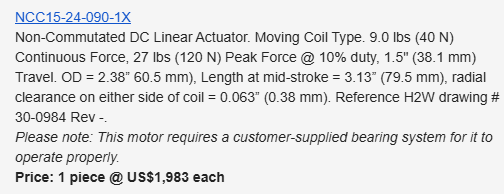

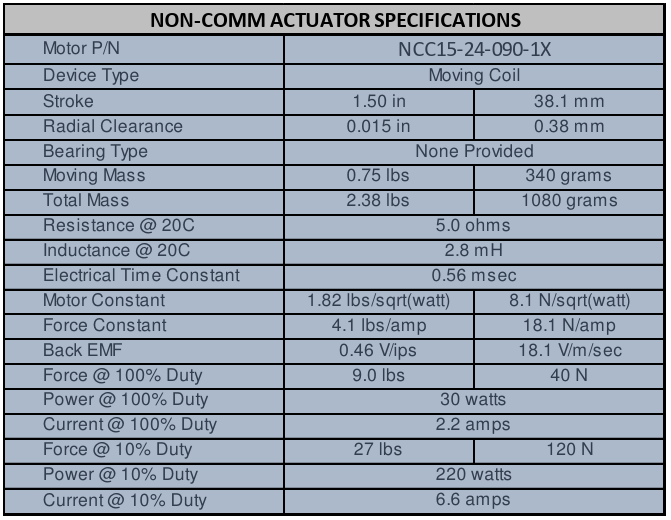

**Looking at Force Requirements (for specified displacement)**

forceConstant  = 4.1;
% calculate required amperage for force requirement
forceReq2 = 16.8787;

forceReq1 = forceReq2/2

forceReq1 = 8.4393


ampReqForce2 = forceConstant*forceReq2

ampReqForce2 = 69.2027


ampReqForce1 = forceConstant*forceReq1

ampReqForce1 = 34.6013



% assume 10% duty... 220 watts to determine required voltage


$$P = IV \$$



$$V = P/I$$


VReqForce2 = 220/ampReqForce2

VReqForce2 = 3.1791


VReqForce1 = 220/ampReqForce1

VReqForce1 = 6.3581



PReqForce2 = VReqForce2*ampReqForce2

PReqForce2 = 220


PReqForce1 = VReqForce1*ampReqForce1

PReqForce1 = 220

Additionally,  at 10% duty meets the force requirement as 27lbs > 16.67 lbf\

**Requires a PSU with > 220 Watts, and the Vin ~= 3.2V**

**Looking at Peak Velocity Requirements (for specified displacement corresponding to Bandwidth via SHM)**

Back EMF is noted to be 0.46 V/ips, and also 18.1 V/m/sec 

% note that vel peak is in meters/s
BEMF = 18.1;
reqVfromBEMF = (velPeakMS*BEMF) % in volts

reqVfromBEMF = 0.1298

reqVfromBEMFSmooth = (velPeakSmoothed*BEMF)

reqVfromBEMFSmooth = 0.0594


% do delta V



% look at the force constant


% calculate wattage requirement
powerReqVCLA = ampReqForce1*reqVfromBEMF + PReqForce2

powerReqVCLA = 224.4927


% 29 kW requirement 

## 3.2.3 Solenoid Actuator

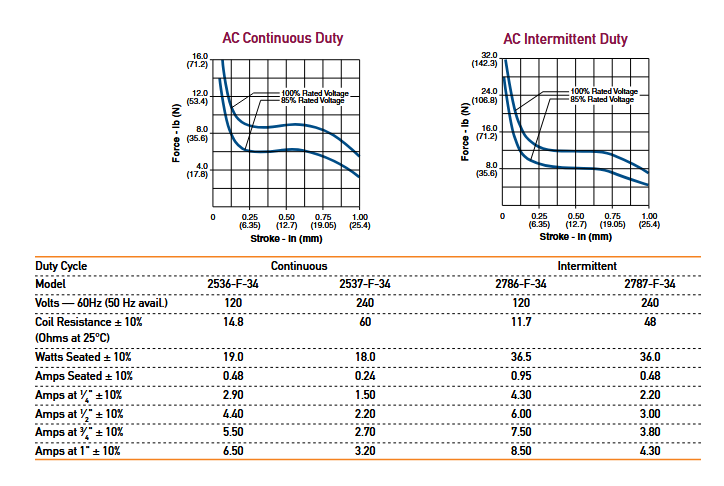

[https://www.johnsonelectric.com/pub/media/image/tmp/metric-imperial/Dormeyer_AC_Laminate_3.pdf](https://www.johnsonelectric.com/pub/media/image/tmp/metric-imperial/Dormeyer_AC_Laminate_3.pdf)

Looking at intermittent Dormeyer 2786-F-34 Solenoid.

strokesInsideQuarterInch = defBendISOEst; % qty to help calculate amperage required

quarterInchAmperage = 4.30 % user inputted from solenoid data above

quarterInchAmperage = 4.3000


% multiplies percentage of quarter that the deflection is by the quarter
% inch amperage to get solenoid amperage as a guesstimate
solenoidAmperage = quarterInchAmperage.*(defBendISOEst/0.25);

% since it is a 120VAC solenoid...
wattageSolenoid = 120*solenoidAmperage

wattageSolenoid =     5.1141
    5.1521
    5.1901
    5.2281
    5.2661
    5.3041
    5.3422
    5.3802
    5.4182
    5.4562
    5.4942
    5.5322
    5.5702
    5.6083
    5.6463


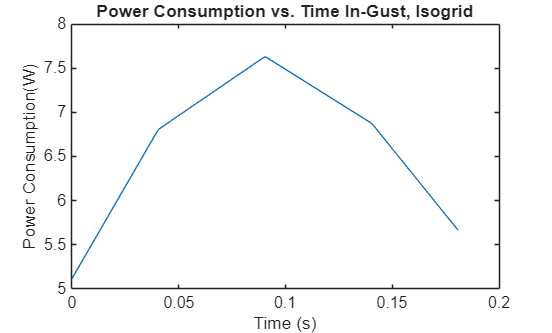


plot(shearTimeArr0Shift, wattageSolenoid)
title('Power Consumption vs. Time In-Gust, Isogrid'); xlabel('Time (s)'); ylabel('Power Consumption(W)')

Need at least a 7.5 watt power supply. Apply an FoS of 2, so I need a 15 watt power supply(at least)

Turning the Force vs. Displcaement graph into a linear equation that is usable

pt1 = [0 32];
pt2 = [.125 18];

slope = (pt2(2) - pt1(2))/(pt2(1) - pt1(1))

slope = -112


yint = pt1(2)

yint = 32


syms x

y1 = slope*x + yint

$$y1 = 32-112\,x$$

Estimate R for solenoid for the calculation...

% approximately
R = (120^2)/wattageSolenoid

% assume time constant of 50s to approximate L
tauc = 0.050
L = tauc*R